# Sattelite Control with Off-Center Reaction Wheels

Press the Initialize button any time the workspace is cleared, this will perform the physics necessary to determine the equations of motion.

 
clear
syms omega omega_dot_ Omega Omega_dot_ d D I M [3 1] real
syms I_s I_p m_w real

r_xb = [D1;d2;d3];
I_Xb = diag([I_s;I_p;I_p]) + m_w*((r_xb'*r_xb)*eye(3) - r_xb*r_xb');
omega_XI = omega + [Omega1;0;0];
omega_dot_XI = omega_dot_ + [Omega_dot_1;0;0];
h_dot_Xb = I_Xb*omega_dot_XI + cross(omega,I_Xb*omega_XI);

r_yb = [d1;D2;d3];
I_Yb = diag([I_p;I_s;I_p]) + m_w*((r_yb'*r_yb)*eye(3) - r_yb*r_yb');
omega_YI = omega + [0;Omega2;0];
omega_dot_YI = omega_dot_ + [0;Omega_dot_2;0];
h_dot_Yb = I_Yb*omega_dot_YI + cross(omega,I_Yb*omega_YI);

r_zb = [d1;d2;D3];
I_Zb = diag([I_p;I_p;I_s]) + m_w*((r_zb'*r_zb)*eye(3) - r_zb*r_zb');
omega_ZI = omega + [0;0;Omega3];
omega_dot_ZI = omega_dot_ + [0;0;Omega_dot_3];
h_dot_Zb = I_Zb*omega_dot_ZI + cross(omega,I_Zb*omega_ZI);

h_dot_Bb = diag(I)*omega_dot_ + cross(omega,diag(I)*omega);

eqns = h_dot_Xb + h_dot_Yb + h_dot_Zb + h_dot_Bb == 0;
eqns(4:6) = I_s*Omega_dot_ == M;

[A,f] = equationsToMatrix(eqns,[omega_dot_;Omega_dot_]);
vars = [omega;Omega;M];

clearvars -except A f vars

Principal values to edit:

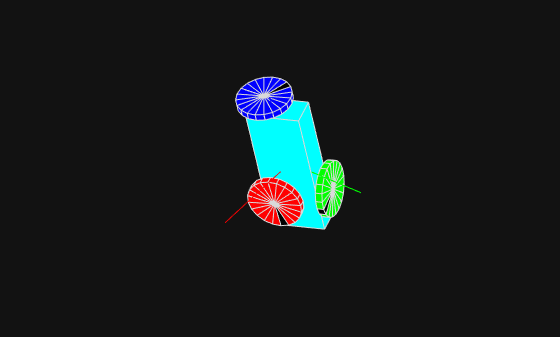

% substitute values
lx = 1;
ly = 2;
lz = 5;
m_b = 50;

r = 0.5*ly;
h = r/4;
m_w = 2;

omega0 = [0;0;0];
Omega0 = [0;0;0];

target = (pi/6)*rand(3,1);
Kp = 0.1; %proportional control coefficient
Kd = 0.2; %derivative control coefficient

tf = 10;
 
% don't edit below this line %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
I1 = (1/12)*m_b*(ly^2+lz^2);
I2 = (1/12)*m_b*(lz^2+lx^2);
I3 = (1/12)*m_b*(lx^2+ly^2);
I_s = (1/2)*m_w*r^2;
I_p = (1/12)*m_w*(3*r^2+h^2);

D1 = (lx+h)/2;
D2 = (ly+h)/2;
D3 = (lz+h)/2;
d1 =-(lx+h)/4;
d2 =-(ly+h)/4;
d3 =-(lz+h)/4;

theta0 = [0;0;0];
psi0 = [0;0;0];

% integrate:
hA = matlabFunction(subs(A),'Vars',{vars});
hf = matlabFunction(subs(f),'Vars',{vars});
hw = @(ang,ome) [sec(ang(2)),0,0;0,1,0;-tan(ang(2)),0,1]*spinmat(3,ang(3))*ome;

% z = theta; psi; omega; Omega
function z_dot = EOM(z,hA,hf,hw,kp,kd,target)
    theta_dot = hw(z(1:3),z(7:9));
    psi_dot = z(10:12);
    
    P = kp*(target-z(1:3));
    D = kd*(-theta_dot);
    M = -(P+D); % applied moment determined by control law
    
    u = hA([z(7:12);M])\hf([z(7:12);M]); %omega_dot;Omega_dot
    
    z_dot = [theta_dot;psi_dot;u];
end

Kp = Kp*diag([I1,I2,I3]);
Kd = Kd*diag([I1,I2,I3]);
[t,z] = ode45(@(t,z) EOM(z,hA,hf,hw,Kp,Kd,target),linspace(0,tf,30*tf),[theta0;psi0;omega0;Omega0]);
z=z';

%animate:
close all
figure(1)
clf
% create body:
prism = hgtransform;
[a,b] = meshgrid([-1,1]/2, [-1,1]/2); c = ones(2)/2;
surf( a*lx, b*ly, c*lz,'FaceColor','c','Parent',prism)
surf( a*lx, b*ly,-c*lz,'FaceColor','c','Parent',prism)
surf( c*lx, a*ly, b*lz,'FaceColor','c','Parent',prism)
surf(-c*lx, a*ly, b*lz,'FaceColor','c','Parent',prism)
surf( b*lx, c*ly, a*lz,'FaceColor','c','Parent',prism)
surf( b*lx,-c*ly, a*lz,'FaceColor','c','Parent',prism)

%draw target orientation:
mat = spinmat([1,2,3],target')*lz*2;
hold on
plot3([0,mat(1,1)],[0,mat(2,1)],[0,mat(3,1)],'r')
plot3([0,mat(1,2)],[0,mat(2,2)],[0,mat(3,2)],'g')
plot3([0,mat(1,3)],[0,mat(2,3)],[0,mat(3,3)],'b')

%create wheels:
[a,b,c] = cylinder;
a=r*a; b=r*b; c=h*(c-1/2);
colrx = cat(3,1,0,0).*ones(size(a)); colrx(1,1,:)=cat(3,0,0,0);
colry = cat(3,0,1,0).*ones(size(a)); colry(1,1,:)=cat(3,0,0,0);
colrz = cat(3,0,0,1).*ones(size(a)); colrz(1,1,:)=cat(3,0,0,0);

X = hgtransform;
r_xb = [D1;d2;d3];
surf(c,a,b,colrx,'Parent',X)
surf((h/2)*ones(2,21),[zeros(1,21);a(1,:)],[zeros(1,21);b(1,:)],colrx,'Parent',X)

Y = hgtransform;
r_yb = [d1;D2;d3];
surf(b,c,a,colry,'Parent',Y)
surf([zeros(1,21);b(1,:)],(h/2)*ones(2,21),[zeros(1,21);a(1,:)],colry,'Parent',Y)

Z = hgtransform;
r_zb = [d1;d2;D3];
surf(a,b,c,colrz,'Parent',Z)
surf([zeros(1,21);a(1,:)],[zeros(1,21);b(1,:)],(h/2)*ones(2,21),colrz,'Parent',Z)


axis equal off
view([160 40])
axis([-1,1,-1,1,-1,1]*lz*0.6)
for i=1:length(t)
    mat = spinmat([1,2,3],z([1,2,3],i)');
    set(prism,'Matrix',[mat,[0;0;0];[0,0,0,1]])
    set(X,'Matrix',[mat*spinmat(1,z(4,i)),mat*r_xb;[0,0,0,1]])
    set(Y,'Matrix',[mat*spinmat(2,z(5,i)),mat*r_yb;[0,0,0,1]])
    set(Z,'Matrix',[mat*spinmat(3,z(6,i)),mat*r_zb;[0,0,0,1]])
    drawnow
end

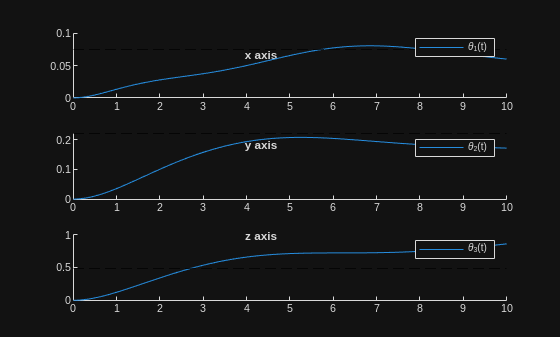

% plot time-histories of euler angles
figure(2)
clf
subplot(3,1,1)
title('x axis')
hold on
plot(t,z(1,:),'DisplayName','\theta_1(t)')
legend('AutoUpdate','off')
yline(target(1),'--k')

subplot(3,1,2)
title('y axis')
hold on
plot(t,z(2,:),'DisplayName','\theta_2(t)')
legend('AutoUpdate','off')
yline(target(2),'--k')

subplot(3,1,3)
title('z axis')
hold on
plot(t,z(3,:),'DisplayName','\theta_3(t)')
legend('AutoUpdate','off')
yline(target(3),'--k')